%正逆运动学分析
mdl_puma560;
p560=SerialLink(p560);
fkine(p560,qz)

 

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


q=[0 -pi/4 -pi/4 0 pi/8 0];
T=fkine(p560,q)

 

T = 
    0.3827         0    0.9239    0.7371
         0         1         0   -0.1501
   -0.9239         0    0.3827   -0.3256
         0         0         0         1


qi=ikine(p560,T)

qi =     0.0000   -0.7854   -0.7854    0.0000    0.3927   -0.0000


q

q =          0   -0.7854   -0.7854         0    0.3927         0


%改变q值，重新进行分析
q1=[0 pi/4 -pi/4 0 pi/8 0]

q1 =          0    0.7854   -0.7854         0    0.3927         0


T1=fkine(p560,q1)

 

T1 = 
    0.9239         0   -0.3827    0.3256
         0         1         0     -0.15
    0.3827         0    0.9239    0.7371
         0         0         0         1


qii=ikine(p560,T1)

qii =     0.0000    0.7854   -0.7854   -0.0000    0.3927    0.0000


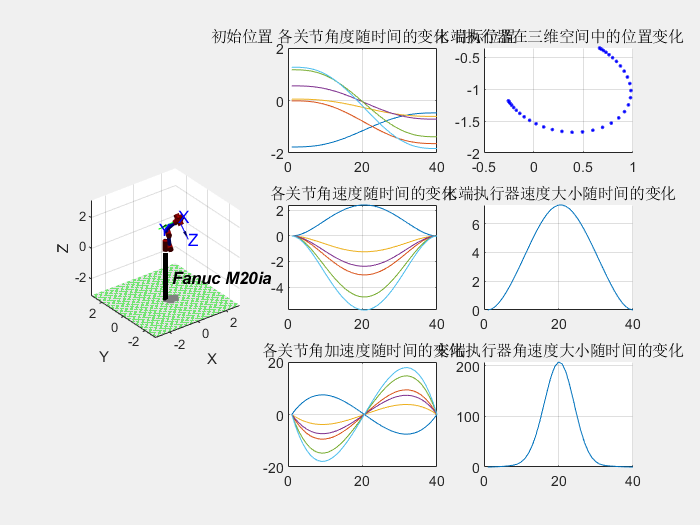

%机器人轨迹规划
%6.1关节空间轨迹规划
%TrajectoryGeneration_p2p_lnksps.m 
clear; 
clc; 
% : theta d a alpha offset 
ML1 = Link([ 0, 0.4967, 0, 0, 0], 'modified');
ML2 = Link([ -pi/2, -0.18804, 0.2, 3*pi/2, 0], 'modified');
ML3 = Link([ 0, 0.17248, 0.79876, 0 , 0], 'modified');
ML4 = Link([ 0, 0.98557, 0.25126, 3*pi/2, 0], 'modified'); 
ML5 = Link([ 0, 0, 0, pi/2 , 0], 'modified'); 
ML6 = Link([ 0, 0, 0, pi/2 , 0], 'modified'); 
robot = SerialLink([ML1 ML2 ML3 ML4 ML5 ML6],'name','Fanuc M20ia');
%给定末端执行器的初始位置
p1 =[ 
0.617222144 0.465154659 -0.634561241 -0.254420286
-0.727874557 0.031367208 -0.684992502 -1.182407321
-0.298723039 0.884673523 0.357934776 -0.488241553
0 0 0 1
]; 
%给定末端执行器的终止位置
p2 = [ 
-0.504697849 -0.863267623 -0.007006569 0.664185871
-0.599843651 0.356504321 -0.716304589 -0.35718173
0.620860432 -0.357314539 -0.697752567 2.106929688
0 0 0 1
]; 
%利用运动学反解 ikine 求解各关节转角
% Inverse kinematics by optimization without joint limits 
% q = R.ikine(T) are the joint coordinates corresponding to the robot end-effector 
% pose T which is an SE3 object or homogenenous transform matrix (4 4), and N is the number of robot joints.
init_ang = robot.ikine(p1);%使用运动学迭代反解的算法计算得到初始的关节角度
targ_ang = robot.ikine(p2);%使用运动学迭代反解的算法计算得到目标关节角度
%利用五次多项式计算关节速度和加速度
% Compute a joint space trajectory 
% [q,qd,qdd] = jtraj(q0, qf, m) is a joint space trajectory q (m N) where the joint 
% coordinates vary from q0 (1 N) to qf (1 N). A quintic (5th order) polynomial is used 
% with default zero boundary conditions for velocity and acceleration. Time is assumed 
% to vary from 0 to 1 in m steps. Joint velocity and acceleration can be optionally returned 
% as qd (m N) and qdd (m N) respectively. The trajectory q, qd and qdd are m*N matrices, with one row per time step, and one column per joint. 
step=40; 
[q,qd,qdd] = jtraj(init_ang, targ_ang, step); 
% 显示机器人姿态随时间的变化
subplot(3,3,[1,4,7]); 
robot.plot(q); 
%显示机器人关节运动状态
subplot(3,3,2); 
i=1:6; 
plot(q(:,i)); 
title('初始位置 各关节角度随时间的变化 目标位置');
grid on; 
subplot(3,3,5); 
i=1:6; 
plot(qd(:,i)); 
title('各关节角速度随时间的变化');
grid on; 
subplot(3,3,8); 
i=1:6; 
plot(qdd(:,i)); 
title('各关节角加速度随时间的变化');
grid on; 
%显示末端执行器的位置
subplot(3,3,3); 
hold on
grid on
title('末端执行器在三维空间中的位置变化');
for i=1:step
position = robot.fkine(q(i,:));
plot3(position.t(1),position.t(2),position.t(3),'b.','MarkerSize',5);
end
%显示末端执行器的线速度与角速度
% Jacobian in world coordinates 
% j0 = R.jacob0(q, options) is the Jacobian matrix (6 N) for the robot in pose q (1 *N), and N is the number of robot joints. The manipulator Jacobian matrix maps joint 
% velocity to end-effector spatial velocity V = j0*QD expressed in the
% world-coordinate frame.
subplot(3,3,6); 
hold on
grid on
title('末端执行器速度大小随时间的变化');
vel = zeros(step,6); 
vel_velocity = zeros(step,1); 
vel_angular_velocity = zeros(step,1); 
for i=1:step
vel(i,:) = robot.jacob0(q(i,:))*qd(i,:)';
vel_velocity(i) = sqrt(vel(i,1)^2+vel(i,2)^2+vel(i,3)^2);
vel_angular_velocity(i) = sqrt(vel(i,4)^2+vel(i,5)^2+vel(i,3)^6); 
end
x = linspace(1,step,step); 
plot(x,vel_velocity); 
subplot(3,3,9); 
hold on
grid on 
title('末端执行器角速度大小随时间的变化');
x = linspace(1,step,step); 
plot(x,vel_angular_velocity); 

%EOF

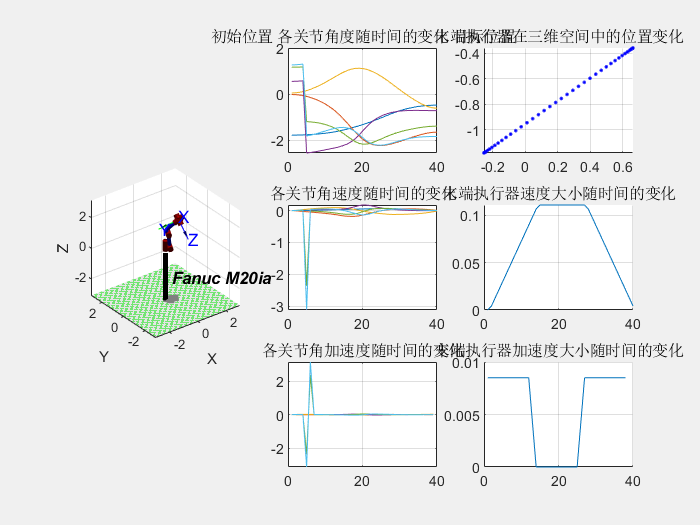

%6.2笛卡尔空间轨迹规划
%TrajectoryGeneration_p2p_Cartesian.m 
clear; 
clc; 
% theta d a alpha offset 
ML1 = Link([ 0, 0.4967, 0, 0, 0], 'modified'); 
ML2 = Link([ -pi/2, -0.18804, 0.2, 3*pi/2, 0], 'modified'); 
ML3 = Link([ 0, 0.17248, 0.79876, 0 , 0], 'modified'); 
ML4 = Link([ 0, 0.98557, 0.25126, 3*pi/2, 0], 'modified'); 
ML5 = Link([ 0, 0, 0, pi/2 , 0], 'modified'); 
ML6 = Link([ 0, 0, 0, pi/2 , 0], 'modified'); 
robot = SerialLink([ML1 ML2 ML3 ML4 ML5 ML6],'name','Fanuc M20ia'); 
%给定末端执行器的初始位置
p1 =[ 
0.617222144 0.465154659 -0.634561241 -0.254420286
-0.727874557 0.031367208 -0.684992502 -1.182407321
-0.298723039 0.884673523 0.357934776 -0.488241553
0 0 0 1
]; 
%给定末端执行器的终止位置
p2 = [ 
-0.504697849 -0.863267623 -0.007006569 0.664185871
-0.599843651 0.356504321 -0.716304589 -0.35718173
0.620860432 -0.357314539 -0.697752567 2.106929688
0 0 0 1
];
%在笛卡尔空间坐标系内，根据梯形速度生成轨迹
% Cartesian trajectory between two poses 
% tc = ctraj(T0, T1, n) is a Cartesian trajectory (4 4 n) from pose T0 to T1 
% with n points that follow a trapezoidal velocity profile along the path. The 
% Cartesian trajectory is a homogeneous transform sequence and the last
% subscript being the point index, that is, T(:,:,i) is the i^th point along the 
% path. 
step = 40; 
Tc = ctraj(p1,p2,step); 
% Inverse kinematics by optimization without joint limits 
% q = R.ikine(T) are the joint coordinates (1 N) corresponding to the robot 
% end-effector pose T which is an SE3 object or homogenenous transform 
% matrix (4 4), and N is the number of robot joints. 
% 显示机器人姿态随时间的变化
subplot(3,3,[1,4,7]); 
q = zeros(step,6); 
for i = 1:step 
q(i,:) = robot.ikine(Tc(:,:,i)); 
end 
robot.plot(q); 
qd = zeros(step-1,6);
for i = 2:step 
qd(i,1) = q(i,1)-q(i-1,1); 
qd(i,2) = q(i,2)-q(i-1,2); 
qd(i,3) = q(i,3)-q(i-1,3); 
qd(i,4) = q(i,4)-q(i-1,4); 
qd(i,5) = q(i,5)-q(i-1,5); 
qd(i,6) = q(i,6)-q(i-1,6); 
end 
qdd = zeros(step-2,6); 
for i = 2:step-1
qdd(i,1) = qd(i,1)-qd(i-1,1); 
qdd(i,2) = qd(i,2)-qd(i-1,2); 
qdd(i,3) = qd(i,3)-qd(i-1,3); 
qdd(i,4) = qd(i,4)-qd(i-1,4); 
qdd(i,5) = qd(i,5)-qd(i-1,5); 
qdd(i,6) = qd(i,6)-qd(i-1,6); 
end 
%显示机器人关节运动状态
subplot(3,3,2); 
i=1:6; 
plot(q(:,i)); 
title('初始位置 各关节角度随时间的变化 目标位置'); 
grid on; 
subplot(3,3,5); 
i=1:6; 
plot(qd(:,i)); 
title('各关节角速度随时间的变化'); 
grid on; 
subplot(3,3,8); 
i=1:6; 
plot(qdd(:,i)); 
title('各关节角加速度随时间的变化'); 
grid on; 
%显示末端执行器的位置
subplot(3,3,3); 
hold on 
grid on 
title('末端执行器在三维空间中的位置变化'); 
for i=1:step 
plot3(Tc(1,4,i),Tc(2,4,i),Tc(3,4,i),'b.','MarkerSize',5); 
end 
%显示末端执行器的速度
subplot(3,3,6);
hold on
grid on 
title('末端执行器速度大小随时间的变化'); 
vel_velocity = zeros(step,1); 
for i=2:step 
vel_velocity(i) = sqrt((Tc(1,4,i)-Tc(1,4,i-1))^2+(Tc(2,4,i)-Tc(2,4,i-1))^2+(Tc(3,4,i)-Tc(3,4,i-1))^2); 
end 
x = linspace(1,step,step); 
plot(x,vel_velocity);
%显示末端执行器的加速度
subplot(3,3,9); 
hold on 
grid on 
title('末端执行器加速度大小随时间的变化'); 
vel_acceleration= zeros(step-2,1); 
for i=3:step 
vel_acceleration(i-2) = sqrt((Tc(1,4,i)-Tc(1,4,i-1)-(Tc(1,4,i-1)-Tc(1,4,i-2)) )^2+( Tc(2,4,i)-Tc(2,4,i-1)-(Tc(2,4,i-1)-Tc(2,4,i-2)) )^2+( Tc(3,4,i)-Tc(3,4,i-1)-(Tc(3,4,i-1)-Tc(3,4,i-2)))^2); 
end 
x = linspace(1,step-2,step-2); 
plot(x,vel_acceleration); 

%EOF